# 2D isentropic inlet

clear; close; clc

## from the DESIGN CRITERIA FOR AXISYMMETRIC AND TWO-DIMENSIONAL SUPERSONIC INLETS AND EXITS - By James F. Connors and Rudolph C. Meyer

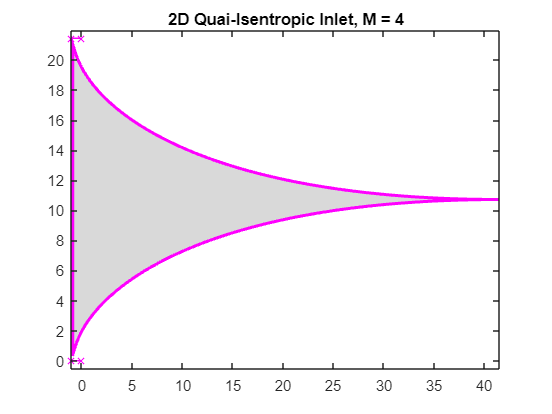

%r and phi are coordinates
gamma = 1.4;
M_0 = 2; % free stream Mach number (~)
r_0 = 1; % something I choose?

figure

for M_0 = [1.1:.1:4]

[x,y,nu] = QuasiIsentropic_Inlet_2D(M_0, 1, 1, gamma, 100);

%plot(x,y); axis("equal"); xlim([0,max(x,[],"all")]); ylim([0,inf]);

%hold on

% plot the line of symmetry
x_sym = linspace(0,5);
y_sym = y(end) + -tan(nu(end)) * (x_sym - x(end));
%plot(x_sym,y_sym, "--r");

%figure
% now rotate into intitive coordinates 
X = [x;y];
theta = -nu(end);
HFB = [cos(theta), sin(theta); -sin(theta), cos(theta)];
X_new = HFB*[x;y];
X_new_upper = -X_new(2,:) + 2*X_new(2,end); % compute the upper surface
%plot(X_new(1,:), X_new(2,:)); axis("equal"); %xlim([0,max(X_new(1,:),[],"all")]); ylim([0,inf]);

%figure;
axis("equal");
boundrayEdges_Xcoords = [X_new(1,:), fliplr(X_new(1,:))];
boundrayEdges_Ycoords = [X_new(2,:), fliplr(X_new_upper)];
fill(boundrayEdges_Xcoords, boundrayEdges_Ycoords, [.5,.5,.5], "FaceAlpha",.3, "EdgeColor",[1,0,1], "LineWidth",2, "DisplayName","Inlet Spike")

% locate and plot the inlet
hold on
X_inlet = [0;0];

% compute the location of the outer inlet rim
X_inlet_upper = X_inlet;
X_inlet_upper(2) = -X_inlet(2) + 2*X_new(2,end); % adjust the second point to be mirrored over the symmerty axis

% plot the inlet
plot([X_inlet(1),-1],[X_inlet(2),0], "Color",[1,0,1], "Marker","x")
plot([X_inlet_upper(1),-1],[X_inlet_upper(2),X_inlet_upper(2)], "Color",[1,0,1], "Marker","x")

xlim([-1,max(X_new(1,:),[],"all")]); ylim([-.5, X_inlet_upper(2)+.5]);
hold off;

title(sprintf("2D Quai-Isentropic Inlet, M = %g",M_0))
pause(.1)
end